# **Authors**

*The work can be done in groups of up to 3 students. Please complete the following fields with your group number and list your names along with ISU ID numbers.*

**Stream: [RZZZ] Technical Vision**

**Subgroup: **

Student ID 1, Name 1

Student ID 2, Name 2

Student ID 3, Name 3

The task and guidelines were prepared by Andrei Zhdanov and Sergei Shavetov from ITMO University in 2024.

# **Practical Assignment No 3. Filtering and Edges Detection**

Studying of the filtering images basic methods and edges detection.

## **Task 1. Noises types**

*Select an arbitrary image. Get images distorted by various noises using the imnoise() function with parameters other than the default values.*

### **1.1 Preparation**

First, we need to clear Command window and Workspace.

clc
clear all

### **1.2 Read and display an image**

Now let's open our image which we will use during the current task using ````imshow(I)` `function. We will open it in RGB mode. We can convert RGB image to grayscale by calling ``rgb2gray(I)`` funtion.

For estimating grayscale image size we may use ``size(Igray)` `function, that returns three parameters: number of rows, number of columns and number of layers. 

% Read an image from file and display its grayscale representation
I = imread('lena_color.png');
Igray = rgb2gray(I);
[numRows, numCols, Layers] = size(Igray);
rows = 3;
cols = 2;
pos = 5;
figure;
subplot(rows,cols,pos);
imshow(Igray);
Ititle{pos} = 'Source Image';
title(Ititle(pos));

### **1.3 Noises**

Digital images obtained by various optoelectronic devices can contain various distortions caused by various kinds of interference, which are commonly called *noise*. The noise in the image makes it difficult to process it automatically. The noises have a different nature, and for its successful suppression it is necessary to determine an adequate mathematical model. Let's consider the most common noise models. In MATLAB ``imnoise()`` function allows adding noise.

#### **1.3.1 Impulse noise**

With impulse noise, the signal is distorted by spikes with very large negative or positive values of short duration and can arise, for example, due to decoding errors. This noise results in white *"salt"* or black *"pepper"* dots in the image, which is why it is often called *dot* noise. To describe it, one should take into account the fact that the appearance of a noise spike in each pixel $I(x,y)$ does not depend on the quality of the original image or on the presence of noise at other points and has the probability of $p$, and the value of the pixel intensity $I(x,y)$ will be changed to value $d\in[0,255]$:


$$    I_{noisy}(x,y) = 
    \begin{cases}
        d      & ~\text{with probability}~p    \\
        I(x,y) & ~\text{with probability}~(1-p)
    \end{cases}$$


where $I(x,y)$ is the pixel intensity of the original image, $I_{noisy}$ is the noisy image, and $p$ is the noise ratio. If $d=0$ then the noise is *"pepper"* type, if $d=255$ then noise is *"salt"*.

Let's implement the impulse noise. In MATLAB we may use ``imnoise(I,'salt & pepper',p)` `function. The salt & pepper noise is controlled by the value ``p` `which is a noise probability in a range` ```[0.00...1.00]```.`

%% Add the salt and pepper noise to an image
p = 0.05;
Inoisy = imnoise(Igray,'salt & pepper', p);
pos = 1;
Inoise(:,:,pos) = Inoisy;
subplot(rows,cols,pos);
imshow(Inoisy)
Ititle{pos} = 'Impulse Noise';
title(Ititle(pos));

#### **1.3.2 Additive noise**

Additive noise is described by the following expression:


$$I_{noisy}(x,y) = I(x,y) + \eta(x,y)$$


where $I_{noisy}$ is the noisy image, $I$ is the original image, and $\eta$ is the signal-independent additive noise with Gaussian or any other probability density function.

We will see an example of an additive noise a bit later in a Gaussian noise section.

#### **1.3.3 Multiplicative Noise**

Multiplicative noise is described by the following expression:


$$I_{noisy}(x,y) = I(x,y) \cdot \eta(x,y)$$


wheew $I_{noisy}$ is the noisy image, $I$ is the original image, and $\eta$ is the signal independent multiplicative noise that multiplies the recorded signal. Examples include film grain, ultrasound images, etc. A special case of multiplicative noise is *speckle* noise. This noise appears in images captured by coherent imaging devices such as medical scanners or radars. In such images, one can clearly observe light spots, speckles, which are separated by dark areas of the image.

Let's implement the multiplicative noise with normal distribution which is called the *speckle* noise using ``imnoise(I,'speckle',var_speckle)` `function in MATLAB**. **Optional ``var_speckle` `parameter defines the variance for the normal distribution used to generate noise.

%% Add the speckle noise to an image
var_speckle = 0.05;
Isp = imnoise(Igray,'speckle',var_speckle);
pos = 2;
Inoise(:,:,pos) = Isp;
subplot(rows,cols,pos);
imshow(Isp);
Ititle{pos} = 'Speckle Noise';
title(Ititle(pos));

#### **1.3.4 Gaussian (Normal) Noise**

Gaussian noise in the additive noise on the image that can occur due to a lack of scene illumination, high temperature, etc. The noise model is widely used in low-pass filtering of images. The probability density distribution function $p(z)$ of the random variable $z$ is described by the following expression:


$$p(z) = \frac{1}{\sigma \sqrt{2\pi}}e^{\frac{-(z-\mu)^2}{2\sigma^2}},$$


where $z$ is the the intensity of the image (for example, for a grayscale image $z\in[0,255]$), $\mu$ is the mean (mathematical expectation) of a random variable $z$, $\sigma$ is the standard deviation, variance $\sigma^2$ determines the power of the introduced noise. Approximately $67%$% of the random variable $z$ values is concentrated in the range $\left[(\mu-\sigma),(\mu+\sigma)\right]$ and about $96%$% in the range $\left[(\mu-2\sigma),(\mu+2\sigma)\right]$.

In MATLAB it can be applied to an image by using `imnoise(I,'gaussian',m,var_gauss)` `function. Optional ``m`` and ``var_gauss`` parameters defines the mean and variance for the normal distribution used to generate noise. The additional ``imnoise(I,'localvar',var_local)`` adds zero-mean, Gaussian white noise of local variance ``var_local```.`

%% Add the gaussian noise to an image
m = 0;
var_gauss = 0.05;
Igauss = imnoise(Igray,'gaussian', m, var_gauss);
pos = 3;
Inoise(:,:,pos) = Igauss;
subplot(rows,cols,pos);
imshow(Igauss);
Ititle{pos} = 'Gaussian Noise';
title(Ititle(pos));

#### **1.3.5 Quantization Noise**

Depends on the selected quantization step and on the signal. Quantization noise can lead, for example, to the appearance of false contours around objects or to remove low-contrast details in the image. Such noise is not eliminated. Quantization noise can be approximately described by the Poisson distribution. 

In MATLAB it can be applied to an image by using ``imnoise(I,'poisson')`` function.

%% Add the poison noise to an image
Ipoisson = imnoise(Igray, 'poisson');
pos = 4;
Inoise(:,:,pos) = Ipoisson;
subplot(rows,cols,pos);
imshow(Ipoisson);
Ititle{pos} = 'Poisson Noise';
title(Ititle(pos));

#### **1.3.6 Noise summary**

So, we learned how to add different type of noise to the digital image in MATLAB.

# ***Self-work***

**Take some arbitrary image and apply different noises to it. Show the results and store them in an array to test filters.**

% TODO Place your solution here







## `Task 2. Low-pass filtering`

*Process of the noised images obtaining in the previous paragraph with considered low-pass filters and a counterharmonic mean filter with different values of the parameter ****𝑄.***

### **2.1 Sliding window filters**

Let's consider the main methods of image filtering. It the neighboring pixels values in a certain neighborhood are taken into account to calculate th intensity value of the each pixel, then such a transformation is called *local*, and the neighborhood is called a *window*. The "window" is called *mask*, *filter*, *filter kernel*, and matrix coefficients are called *coefficients*. The center of the mask is aligned with the analyzed pixel, and the mask coefficients are multiplied by the intensities of the pixels covered by the mask. Typically, the mask has a square shape of $3\times 3$, $5\times 5$, etc. Filtering an $M\times N$ image $I$ using a mask of $m\times n$ size is described by the formula:


$$I_{filtered}(x,y) = \sum_s \sum_t w(s,t)I(x+s, y+t)$$


where $s$ and $t$ are the coordinates of the mask elements relative to its center (in the center $s=t=0$). Such transformations are called *linear*. After calculating the new value of the pixel intensity $I_{filtered}(x,y)$ window $w$, in which the filter mask is described, it is shifted and the intensity of the next pixel is calculated. Therefore, such a transformation is called *sliding window filtering*. 

When using MATLAB image filtering can be performed by calling the ``filter2(mask,I)``, where matrix ``mask`` sets the filter mask. The mask can be set either manually or using the function ``fspecial(type, size)``**.** Optional paramaters ``type`` and ``size` `define filter type and its size, e.g. for averaging filter with a size mask 3 $\times$ 3 you may use:

mask = fspecial('average',3);

`2.2 Low-pass filter kernels`

Low-pass spatial filters attenuate the high-pass components (areas with large intensity changes) and leave the low-pass components of the image unchanged. Used to reduce noise and remove high-pass components, which improves the accuracy of the study of the content of low-pass components. As a result of applying low-pass filters, we get a smoothed or blurred image. The main distinguishing features are:

- non-negative mask coefficients;

- the sum of all coefficients is equal to one.

Examples of low-pass filter kernels:


$$
w_{1}=\frac{1}{9}  \left[ \matrix{ 1 & 1&1 \cr 1 & 1&1 \cr 1 &1&1} \right] , w_{2}=\frac{1}{10} \left[ \matrix{ 1 & 1&1 \cr 1 & 2&1 \cr 1 &1&1} \right] .$$


`Let's try running the low-pass filter with these kernels for all our four noise types. First we implement kernel `$w_2$`.`

figure
Inoise = double(Inoise) / 255;
mask = (1 / 9) * ones(3, 3);
for i = 1:4
    Iw(:,:,i) = filter2(mask, Inoise(:,:,i));
    subplot(rows,cols,i);
    imshow(Iw(:,:,i));
    title(strcat('Filtered W: ', Ititle(i)));
end
pos = i + 1;
subplot(rows,cols,pos);
imshow(Igray);
title(Ititle(pos));

# ***Self-work***

**Run the low-pass 2D filter with kernel **$w_2$** for all noise types.**

% TODO Place your solution here







### **2.3 Arithmetic mean filter**

This filter averages the pixel intensity value over the neighborhood using a mask with the same coefficients, for example, for a mask with the size $3 \times 3$ the coefficients are $1/9$, if $5 \times 5$ $-$ $1/25$. Thanks to this normalization, the value of the filtering result will be reduced to the original image intensities range. Graphically, the two-dimensional function describing the filter mask looks like a parallelepiped, so the name is used in English literature *box*-filter. Arithmetic averaging is achieved using the following formula:


$$I_{filtered}(x,y) = \frac{1}{m \cdot n} \sum_{i=0}^m \sum_{j=0}^n I(i,j)$$


where $I_{filtered}(x,y)$ is the value of the filtered image pixel intensity, $I(i,j)$ is the the value of the original image in the mask pixels intensities, $m$ and $n$ are the filter mask width and height respectively. This algorithm is effective for slightly noisy images. In MATLAB it can be executed by using the function ``filter2(fspecial('average',3),I)`` for $3 \times 3$ filter kernel.

figure
mask = fspecial('average',3);
for i = 1:4
    IfiltA(:,:,i) = filter2(mask, Inoise(:,:,i));
    subplot(rows,cols,i);
    imshow(IfiltA(:,:,i));
    title(strcat('Filtered A: ', Ititle(i)));
end
pos = i + 1;
subplot(rows,cols,pos);
imshow(Igray);
title(Ititle(pos));

### **2.4 Geometric mean filter**

Geometric averaging is calculated using the formula:


$$I_{filtered}(x,y) = \left[\prod_{i=0}^{m}\prod_{j=0}^{n} I(i,j)\right]^{\frac{1}{m \cdot n}}$$


The effect of applying this filter is similar to the previous method, but individual objects in the original image are less distorted. The filter can be used to suppress high-pass additive noise with better statistical performance than an arithmetic averaging filter.

This filter can be easily implemented via arithmetic mean filter since $\prod_{i}x_i = e^{\sum_{i}\ln{}x_i}$, so


$$I_{filtered}(x,y) = \left[\prod_{i=0}^{m}\prod_{j=0}^{n} I(i,j)\right]^{\frac{1}{m \cdot n}} = \left[e^{\sum_{i=0}^{m}\sum_{j=0}^{n} \ln{I(i,j)}}\right]^{\frac{1}{m \cdot n}}$$


Let's implement it for a $5 \times 5$ kernel.

figure
filterSize = 5;
clipImage = (filterSize - 1) / 2;
for i = 1:4
    IfiltG(:,:,i) = Inoise(:,:,i);
    f = IfiltG(:,:,i);
    resultImage = f;
    for j = 1 + clipImage:numRows - clipImage
        for k = 1 + clipImage:numCols - clipImage
            is = f(j - clipImage:j + clipImage, k - clipImage:k + clipImage);
            resultImage(j,k) = prod(prod(is(:))) ^ (1 / numel(is));
        end
    end
    IfiltG(:,:,i) = resultImage;
    subplot(rows,cols,i);
    imshow(IfiltG(:,:,i));
    title(strcat('Filtered G: ', Ititle(i)));
end
pos = i + 1;
subplot(rows,cols,pos);
imshow(Igray);
title(Ititle(pos));

### **2.5 Harmonic mean filter**

The filter is based on the expression:


$$I_{filtered}(x,y) = \frac{m \cdot n}{ \sum_{i=0}^m \sum_{j=0}^n \frac{1}{I(i,j)}}$$


The filter suppresses *"salt"* noise well and does not work with *"pepper"* noise.

Let's apply it to our noisy images with for a $5 \times 5$ kernel.

figure
filterSize = 5;
clipImage = (filterSize - 1) / 2;
for i = 1:4
    IfiltH(:,:,i) = Inoise(:,:,i);
    f = IfiltH(:,:,i);
    resultImage = f;
    for j = 1 + clipImage:numRows - clipImage
        for k = 1 + clipImage:numCols - clipImage
            is = f(j - clipImage:j + clipImage, k - clipImage:k + clipImage);
            is = 1 ./ is; 
            resultImage(j,k) = numel(is) / sum(is(:));
        end
    end
    IfiltH(:,:,i) = resultImage;
    subplot(rows,cols,i);
    imshow(IfiltH(:,:,i));
    title(strcat('Filtered H: ', Ititle(i)));
end
pos = i + 1;
subplot(rows,cols,pos);
imshow(Igray);
title(Ititle(pos));

It can be seen that *"pepper"* noise got worse, but *"salt"* was cleaned.

### **2.5 Contra Harmonic (Inverse) Mean Filter**

The filter is based on the expression:


$$I_{filtered}(x,y) = \frac{\sum_{i=0}^m \sum_{j=0}^n I(i,j)^{Q+1}}{\sum_{i=0}^m \sum_{j=0}^n I(i,j)^Q }$$


where $Q$ is the filter order. The contra harmonic filter is a generalization of the averaging filters and for $Q>0$ suppresses noises of the *"pepper"* type, and if $Q<0$ then noises of the *"salt"* type, however, it is not possible to remove white and black points at the same time. If $Q=0$ the filter turns into an arithmetic one, and if $Q=-1$ then to the harmonic one.

Implementation of the contr harmonic mean filter is very similar to a harmonic one. The only difference is that now we have to calculate top and bottom parts for the whole image separately, and then divide them.

# ***Self-work***

**Finish the implementation of the counterharmonic mean filter.**

figure
Q1 = 1;
filterSize = 5;
clipImage = (filterSize - 1) / 2;
for i = 1:4
    IfiltCH(:,:,i) = Inoise(:,:,i);
    f = IfiltCH(:,:,i);
    resultImage = f;
    for j = 1 + clipImage:numRows - clipImage
        for k = 1 + clipImage:numCols - clipImage
            is = f(j - clipImage:j + clipImage, k - clipImage:k + clipImage);
            % TODO Place your solution here
            % resultImage(j,k) = 
        end
    end
    IfiltCH(:,:,i) = resultImage;
    subplot(rows,cols,i);
    imshow(IfiltCH(:,:,i));
    title(strcat('CH Filtered: ', Ititle(i)));
    
end
pos = i + 1;
subplot(rows,cols,pos);
imshow(Igray);
title(Ititle(pos));

# ***Self-work***

**Try different **$Q$** parameter values and tell which works better with different noise types.**

% TODO Place your solution here







### **2.6 Gaussian filter**

The pixels in the sliding window that are closer to the analyzed pixel should have a greater influence on the filtering result than the extreme ones. Therefore, the mask weight coefficients can be described by the bell-shaped Gaussian function. During images filtering, a two-dimensional Gaussian filter is used:


$$G_{\sigma}=\frac{1}{2\pi\sigma^2}e^{-\frac{x^2+y^2}{2\sigma^2}}=\frac{1}{\sigma\sqrt{2\pi}}e^{\frac{-x^2}{2\sigma^2}}\cdot\frac{1}{\sigma\sqrt{2\pi}}e^{\frac{-y^2}{2\sigma^2}}$$


The larger the parameter $\sigma$, the more the image is blurred. Typically the filter radius $r=3\sigma$. In this case, the mask size $2r+1\times 2r+1$ and the matrix size is $6\sigma+1\times 6\sigma+1$. Outside this neighborhood, the values of the Gaussian function will be negligible.

MATLAB provides a function for Gaussian filter called ``imgaussfilt(A,sigma)```. `The additional parameter ``sigma`` is used to specify $\sigma$ value.

# ***Self-work***

**Run the Gaussian blur filter for noisy images. Use **$\sigma$** value **$1$**. Which type of noise does this filter works better with?**

% TODO Place your solution here







## **Task 3. Nonlinear filtering**

*Process the distorted images obtained in the first point with median, weighted median, rank and Wiener filtering for different sizes of the mask and its coefficients.*

*Optional: Implement adaptive median filtering.*

Low-pass filters are linear and are optimal when there is a normal distribution of noise in the digital image. Linear filters locally average impulse noise, smoothing images. To eliminate impulse noise, it is better to use non-linear filters, for example, *median* filters.

### **3.1 Median filter**

The classical median filter uses a mask with unit coefficients. An arbitrary window shape can be set using zero coefficients. The pixel intensities in the window are represented as a column vector and sorted in ascending order. The filtered pixel is assigned the median (mean) intensity value in the series. The median element number after sorting can be calculated by the formula $n=\frac{N+1}{2}$, where $N$ is the number of pixels involved in sorting. When using MATLAB, the median filter can be executed by calling **`medfilt2(I,[m n])`** function, where parameters **`m`** and **`n`** define neighborhood around the corresponding pixel in the input image.

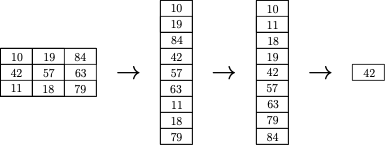

`Median filter`

# ***Self-work***

**Run the median filter for noisy images. Which type of noise does this filter works better with?**

% TODO Place your solution here




  
  

### **3.2 Weighted median filter**

In this median filtering modification in the mask, weights are used (numbers $2, 3$ etc.) to reflect more influence on the filtering result of pixels located closer to the element to be filtered. Each item is added the giver number of times to the array before sorting. Median filtering qualitatively removes impulse noise, and also does not introduce new intensity values in grayscale images. Increasing the size of the window increases the filter noise-canceling ability, but the objects outlines begin to distort. OpenCV does not profive weighted median filter, but it can be implemented.

%% Weighted median filter
figure
filterSize = 3;
clipImage = (filterSize - 1) / 2;
mask = [1 2 1; 2 3 2; 1 2 1];
rank = (sum(mask(:)) + 1) / 2;
for i = 1:4
    IfiltWMF(:,:,i) = Inoise(:,:,i);
    f = IfiltWMF(:,:,i);
    resultImage = f;
    for j = 1 + clipImage:numRows - clipImage
        for k = 1 + clipImage:numCols - clipImage
            is = f(j - clipImage:j + clipImage, k - clipImage:k + clipImage);
            layer_stack = zeros(1, sum(mask(:)));
            k2 = 1;
            for i1 = 1:filterSize
                for j1 = 1:filterSize
                    for k1 = 1:mask(i1,j1)
                        layer_stack(k2) = is(i1,j1);
                        k2 = k2 + 1;
                    end
                end
            end
            layer_stack = sort(layer_stack);
            resultImage(j,k) = layer_stack(rank);
        end
    end
    IfiltWMF(:,:,i) = resultImage;
    subplot(rows,cols,i);
    imshow(IfiltWMF(:,:,i));
    title(strcat('Filtered WMF: ', Ititle(i)));
end
pos = i + 1;
subplot(rows,cols,pos);
imshow(Igray);
title(Ititle(pos));

### **3.3 Rank filter**

A median filtering generalization is a *rank filter* of order $r$ which selects a pixel with the given number from the resulting column vector of mask elements $r\in[1,N]$, which will be the result of filtering.

- If the number of pixels in the window $N$ is odd and $r=\frac{N+1}{2}$, then the rank filter is *median*. In MATLAB you can use ``ordfilt2(I,rank,mask)` `function, where **`rank`** variable is an order of the filter

- If $r=1$ (**`rank = 1`**), the filter selects the lowest intensity value and is called *min-filter*.

- If $r=N$ (**`rank = N`**), the filter selects the maximum intensity value and is called *max-filter*.

Sometimes rank is written as a percentage, for example, for *min-filter* rank is $0%$, *median* filter is $50%$, *max-filter* is $100%$.

It can be noted that when implementing the weighted median filter we already had the **`rank`** variable which was used to find the median in the varying length array. We can make it a filter parameter to make it the weighted rank filter.

%% Rank filter
figure
mask = ones(3,3);
rank = (sum(mask(:)) + 1) / 2;
for i = 1:4
    IfiltRF(:,:,i) = ordfilt2(Inoise(:,:,i),rank,mask);
    subplot(rows,cols,i);
    imshow(IfiltRF(:,:,i));
    title(strcat('Filtered RF: ', Ititle(i)));
end
pos = i + 1;
subplot(rows,cols,pos);
imshow(Igray);
title(Ititle(pos));

# ***Self-work***

**Run the rank filter for **$min$** and **$max$** parameter values with all noise types.**

Run the $min$ rank filter.

% TODO Place your solution here







Run the $max$ rank filter.

% TODO Place your solution here







### **3.4 Adaptive median filter**

In this filter modification, a sliding window of size $s\times s$ adaptively increases depending on the filtering result. Let us denote by $z_{min}$, $z_{max}$, $z_{med}$ minimum, maximum and median values of intensities in the window, $z_{i,j}$ is the pixel intensity value with coordinates $(i,j)$, $s_{max}$ is the maximum allowable window size. The adaptive median filtering algorithm consists of the following steps:

1. Calculating values $z_{min}$, $z_{max}$, $z_{med}$, $A_1=z_{med}-z_{min}$, $A_2=z_{med}-z_{max}$ of the pixel $(i,j)$ in the given window. 

    1) If $A_1>0$ and $A_2<0$, go to step 2. Otherwise, increase the window size.

    2) If the current window size is $s >= s_{max}$, repeat step 1. 

    3) Otherwise, the filtering result is $z_{i,j}$.

2. Calculating values $B_1=z_{i,j}-z_{min}$, $B_2=z_{i,j}-z_{max}$.

    1. If $B_1>0$ and $B_2<0$, the filtering result is $z_{i,j}$. 

    2. Otherwise, the filtering result is $z_{med}$.

3. Change coordinates $(i,j)$.

    1. If the image limit is not reached, go to step 1. 

    2. Otherwise, the filtering is over.

The main idea is to increase the window size until the algorithm finds a median value that is not impulse noise, or until it reaches the maximum window size. In the latter case, the algorithm will return the value $z_{i,j}$.

# `Self-work`

`OPTIONAL`**: 1 extra point**

`Implement the adaptive median filter and run it with different noise types.`

%% Adaptive median filter







`Now run the adaptive median filter for all noise types. Compare the results.`

%% Adaptive median filter







### **3.5 Wiener filter**

Weiner filter uses Wiener's pixel-adaptive method based on statistics estimated from the local neighborhood of the each pixel.


$$\mu=\frac{1}{n\cdot m}  \sum_{i=0}^{m}\sum_{j=0}^{n} I(i,j)$$



$$\sigma^2=\frac{1}{n\cdot m}  \sum_{i=0}^{m}\sum_{j=0}^{n} I^2(i,j)-\mu^2$$



$$I_{new}(x,y)=\mu+\frac{\sigma^2-v^2}{\sigma^2}\left(I(x,y)-\mu\right)$$


Where $\mu$ is the average in the neighborhood, $\sigma^2$ is the variance, and $v^2$ is the noise variance. In MATLAB you may use **`wiener2(I,[m n])`**, where parameters **`m`** and **`n`** specifies the size (`m`-by-`n`) of the neighborhood used to estimate the local image mean and standard deviation.

%% The Weiner filter
figure
for i = 1:4
    IfiltWiener(:,:,i) = wiener2(Inoise(:,:,i),[3 3]);
    subplot(rows,cols,i);
    imshow(IfiltWiener(:,:,i));
    title(strcat('Filtered Wiener: ', Ititle(i)));
end
pos = i + 1;
subplot(rows,cols,pos);
imshow(Igray);
title(Ititle(pos));

# `Self-work`

`Run the Weiner filter with all of our noisy images. Use the `$5 \times 5$` kernel filled with `$1$`.`

% TODO Place your solution here







## **Task 4. High-pass filtering**

*Select source image. Detect edges with Roberts, Prewitt, Sobel, Laplace filters, Canny algorithm.*

High-pass spatial filters enhance high-pass components (areas of strong intensity variation) and attenuate low-pass components of the image. They are used to highlight intensity differences and define edges (contours) in images. As a result of applying high-pass filters, the image is sharpened.

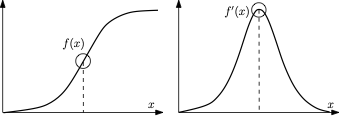

*High-pass Filter*

 *Intensity function and its first derivative, the maximum of the derivative corresponds to the edge*

High-pass filters approximate the computation of directional derivatives, while the increment of the argument $\Delta x$ is taken equal to 1 or 2. The main distinctive features are:

- filter mask coefficients can take negative values;

- the sum of all coefficients is zero.

### **4.1 Roberts filter**

The Roberts filter works with the minimum dimensionality mask allowed for the derivative calculation $2 \times 2$, therefore it is fast and quite efficient. Possible options for masks for finding the gradient along the axes $Ox$ and $Oy$:


$$G_{x}=\left[ \matrix{ 1 & -1 \cr 0 & 0} \right], G_{y}=\left[ \matrix{ 1 & 0 \cr -1 & 0} \right] ,$$


or


$$G_{x}=\left[ \matrix{ 1 & 0 \cr 0 & -1} \right], G_{y}=\left[ \matrix{ 0 & 1 \cr -1 & 0} \right].$$


As a result of applying the Roberts differential operator, we obtain an estimate of the gradient in the directions $G_x$ and $G_y$. The all edge detectors gradient modulus can be calculated by the formula $G=\sqrt{G_x^2+G_y^2}=|G_x|+|G_y|$, and gradient direction by the formula $\arctan{ \left(\frac{G_y}{G_x}\right) }$. 

In MATLAB it is implemented by calling ``edge(I,'Roberts')`` function. As this filter is not used to filter noise, so we will run it for our initial image and check what edges are found.

%% The Roberts filter
Iroberts = edge(Igray,'Roberts');
figure;
imshow(Iroberts);

Instead of using built-in function ``edge()`` we can realize it using formulas above.

% Converting grayscale representation to black & white image
Igray = im2double(Igray);
Ibw = imbinarize(Igray);

% Define kernels for X and Y
kernel_x = [1  0; 0  -1];
kernel_y = [0  1; -1 0];

% Perform convolution
Ix = imfilter(Ibw, kernel_x, 'conv', 'same');
Iy = imfilter(Ibw, kernel_y, 'conv', 'same');

% Calculate of magnitude
Iroberts2 = sqrt(Ix.^2 + Iy.^2);

%Display edges
figure;
imshow(Iroberts2);

### **4.2 Prewitt Filter**

This approach uses two orthogonal masks of size $3\times 3$, allowing you to more accurately calculate the derivatives along the axes $Ox$ and $Oy$:


$$G_{x}= \left[ \matrix{ -1 & 0 & 1 \cr -1 & 0& 1 \cr -1&0&1} \right],
G_{y}= \left[ \matrix{ -1 & -1 & -1 \cr 0 & 0& 0 \cr 1&1&1} \right].$$


Implementation is very similar to implementation of the Roberts filter. In MATLAB you can use ``edge(I,'Prewitt')`` function. 

# `Self-work`

`Implement the Prewitt filter ``without`` using MATLAB `edge(I, 'Prewitt')` function. Run this filter with the source image. Go to Roberts filter for tips.`

% TODO Place your solution here







### **4.3 Sobel filter**

This approach is similar to the Roberts filter, but different mask weights are used. A typical example of a Sobel filter:


$$G_{x}= \left[ \matrix{ -1 & 0 & 1 \cr -2 & 0& 2 \cr -1&0&1} \right],
G_{y}= \left[ \matrix{ 1 & 2 & 1 \cr 0 & 0& 0 \cr -1&-2&-1} \right].$$


This filter can be implemented manually as was described above or can use ``edge(I,'Sobel')`` MATLAB function. 

# `Self-work`

`Implement the Sobel filter ``without`` using MATLAB `edge()` function. Run this filter with the source image. Go to Roberts filter for tips.`

% TODO Place your solution here







### **4.4 Laplace filter**

Laplace filter uses approximation of the second derivatives along the axes $Ox$ and $Oy$ as opposed to previous approaches using the first derivative:

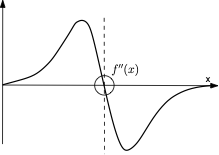

*Laplace filter*

*The second derivative of the brightness function changes sign (passes through zero at the point corresponding to the edge)*


$$L(I(x,y)) = \frac{\partial^2 I}{\partial x^2}+\frac{\partial^2 I}{\partial y^2}$$


The above formula can be approximated by the following mask:


$$w= \left[ \matrix{ 0 & -1 & 0 \cr -1 & 4& -1 \cr 0&-1&0} \right].
$$


Let's implement this filter according to a given forumla. It should be noted that this filter gives us the gradient, in other words, it can result in the negative values. For display purposes we will use the absolute value of the Laplace filter result (by applying **`np.abs()`** to the floating point value result before converting back to **`uint8`**). However in real cases this filter result should be used as is in floating point values for the further image processing steps.

There is the **`edge(I,'log')`** MATLAB function, however it **doesn't implement the Laplace filter directly**, *instead of this it uses laplacian of gaussians approximation*.

# `Self-work`

`Implement the Laplace filter ``without`` using MATLAB ``**edge(I,'log')**`` function. Run the Laplace filter implementation with the source image.`

% TODO Place your solution here








### **4.5 Canny algorithm**

One of the most widespread and efficient algorithms for extracting edges in an image is *Canny algorithm*. This algorithm allows not only to define edge pixels, but also connected boundary lines. The algorithm consists of the following steps:

1. Elimination of small details by smoothing the original image using a Gaussian filter.

2. Using the Sobel differential operator to determine the values of the all image pixels gradient modulus, and the calculation result is rounded by steps $45^{\circ}$.

3. Analysis of the gradient modules values of the pixels located orthogonally to the investigated one. If the gradient modulus value of the investigated pixel is greater than orthogonal neighboring pixels, then it is *edge*, otherwise it is *non-maximum*.

4. Performing double threshold filtering of edge pixels selected in the previous step:

 - If the gradient modulus value greater the threshold $t_2$, then the edge presence in a pixel is valid.

 - If the gradient modulus value lower the threshold $t_1$, then the pixel is definitely not edge.

 - If the gradient modulus value in a range of $[t_1, t_2]$, then such a pixel is considered as $\textit {ambiguous}$.

5. Suppresses all ambiguous pixels not associated with valid pixels by 8-connectivity.

In OpenCV the Canny algorithm can be executed using ``edge(I, 'Canny')`` function.

Icanny = edge(Ibw, 'Canny');
figure;
imshow(Icanny);

# ***Self-work***

**Run the Canny algorithm for your image.**

% TODO Place your solution for optional task here







### **4.6 High-pass filters summary**

Let's check all high-pass filter results side-by-side.

% TODO Place your solution for optional task here
% use subplot with 2 rows and 3 columns for displaying:
% Igray,  Iroberts, Iprewitt, 
% Isobel, Ilaplace, Icanny








# ***Self-work***

**Answer questions and conclude your work results.**

## **Questions**

Please answer the following questions:

 -  What are the main disadvantages of adaptive image filtering methods?

** > Put your answer here**

 - Which value of the $Q$ parameter will make the counterharmonic filter to work work as an arithmetic mean filter, and which value will make it a harmonic one?

** > Put your answer here**

 - What operators can be used to detect edges in the image?

** > Put your answer here**

 - Why, as a rule, is low-pass filtering performed at the first step of edge detection?

** > Put your answer here**

## **Conclusion**

What have you learned with this task? Don't forget to conclude it.

 **> Put your answer here**